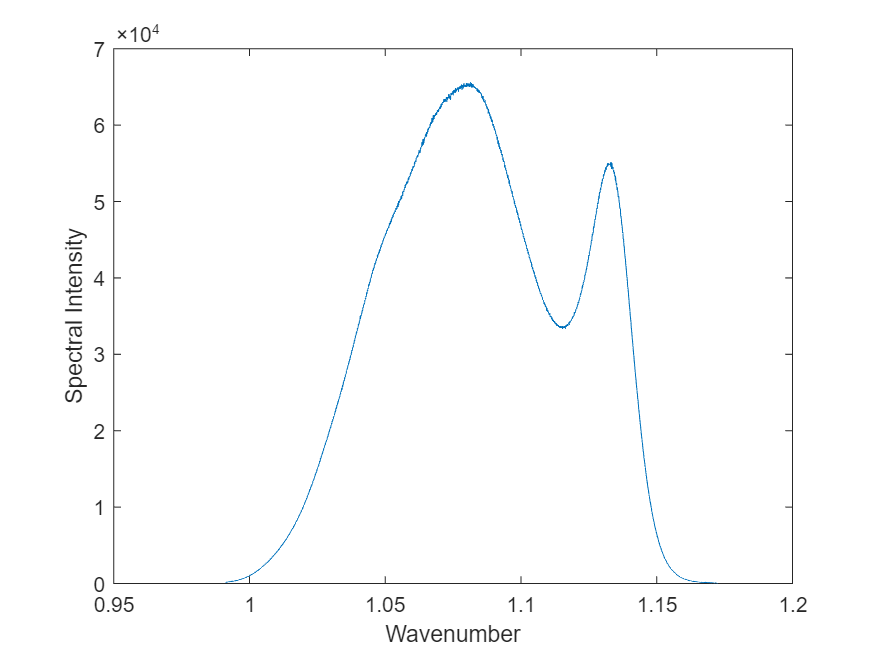

clear; clc;
format short g
%Original spectral interference signal
handle  = OCTFileOpen('Default_0193_Mode2D.oct');
NrRawData = OCTFileGetNrRawData(handle);
[RawData, Spectrum] = OCTFileGetRawData(handle, 0);
load('Wavelength.mat','Wavelength');
intensity = zeros(1,length(Spectrum));
wavelength = zeros(1,length(Wavelength));
for i = 1:length(Wavelength)
    wavelength(length(wavelength)+1-i) = Wavelength(i);
    intensity(length(intensity)+1-i) = Spectrum(i);
end
%波长映射到波数
sigma = 1./wavelength;
%波数均匀采样
sigma_inter = linspace(sigma(1),sigma(end),length(sigma)); 
%光谱强度三次样条插值
intensity_inter = spline(sigma,intensity,sigma_inter);
figure(4);plot(sigma_inter,intensity_inter);
xlabel('Wavenumber');ylabel('Spectral Intensity');

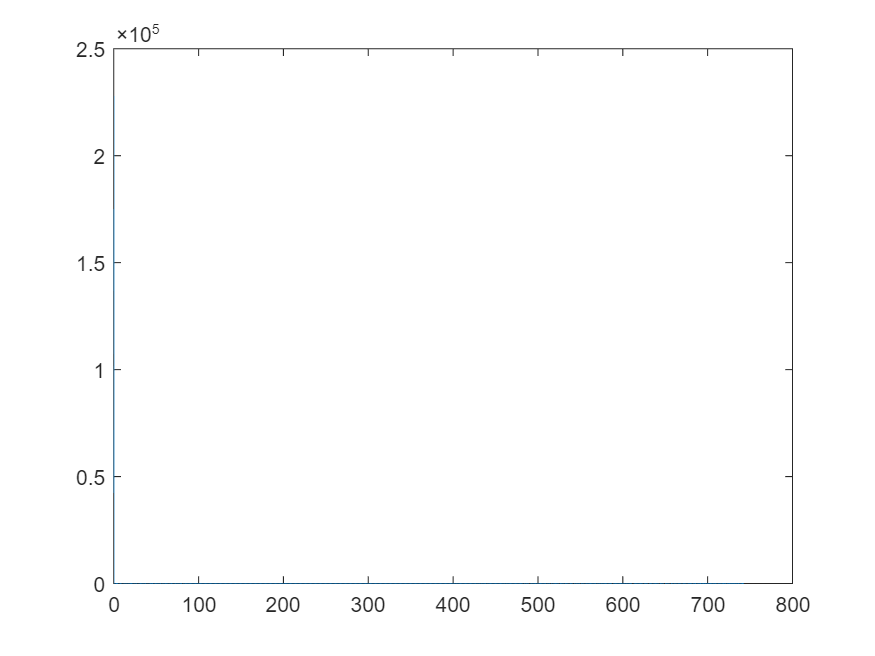

%光谱干涉信号S(\sigma) = A(\sigma)*cos(4\pi*(z-z0)*\sigma-4\pi*T*n(\sigma)*\sigma)
spec_signal = intensity_inter;
y = spec_signal.*cos(4*pi*500*sigma_inter)+spec_signal.*cos(4*pi*700*sigma_inter)+spec_signal.*cos(4*pi*900*sigma_inter)+...
    +spec_signal.*cos(4*pi*1100*sigma_inter)+spec_signal.*cos(4*pi*1300*sigma_inter)+spec_signal.*cos(4*pi*1500*sigma_inter)+...
    spec_signal.*cos(4*pi*1700*sigma_inter);
y_fft = fft(y,2^20);
deltaSigma = (sigma_inter(end)-sigma_inter(1))/(length(sigma_inter)-1);
deltaZ = 1/(2*2^23*deltaSigma);
y = y_fft(1:length(y_fft)/2);
y = ifft(y,2^23);
deltasigma = 1/(2*2^23*deltaZ);
sigma = (1:2^23)*deltasigma;
plot(sigma,abs(y));

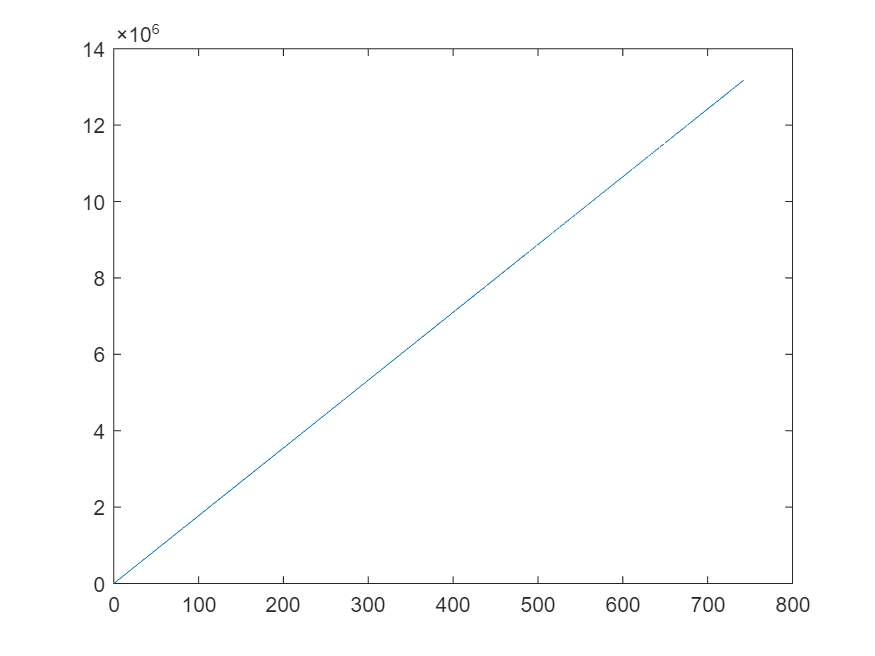

plot(sigma,unwrap1(unwrap(angle(y))));

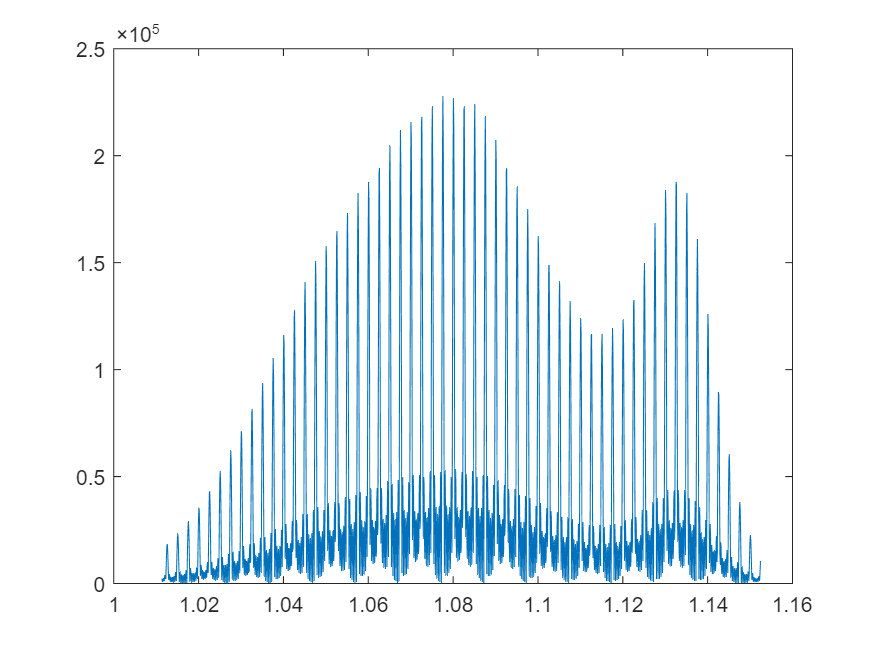

%坐标变换
sigma = sigma+sigma_inter(1);
[~, indix_min] = min(abs(sigma-sigma_inter(1)-0.02));%sigma_inter(1)
[~, indix_max] = min(abs(sigma-sigma_inter(end)+0.02));%sigma_inter(end)
sigma = sigma(indix_min:indix_max);
y = y(indix_min:indix_max);
plot(sigma,abs(y));

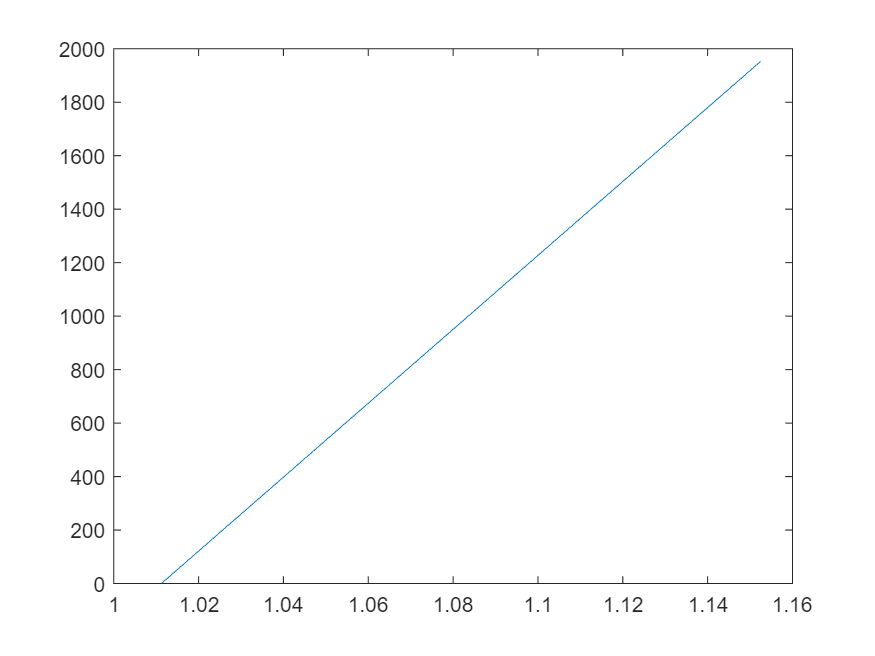

% 过零点存在问题
angle_fit = unwrap(angle(y));
angle_fit = unwrap1(angle_fit);
poly = polyfit(sigma,angle_fit,1);
ang_fit = polyval(poly,sigma);
plot(sigma,angle_fit);

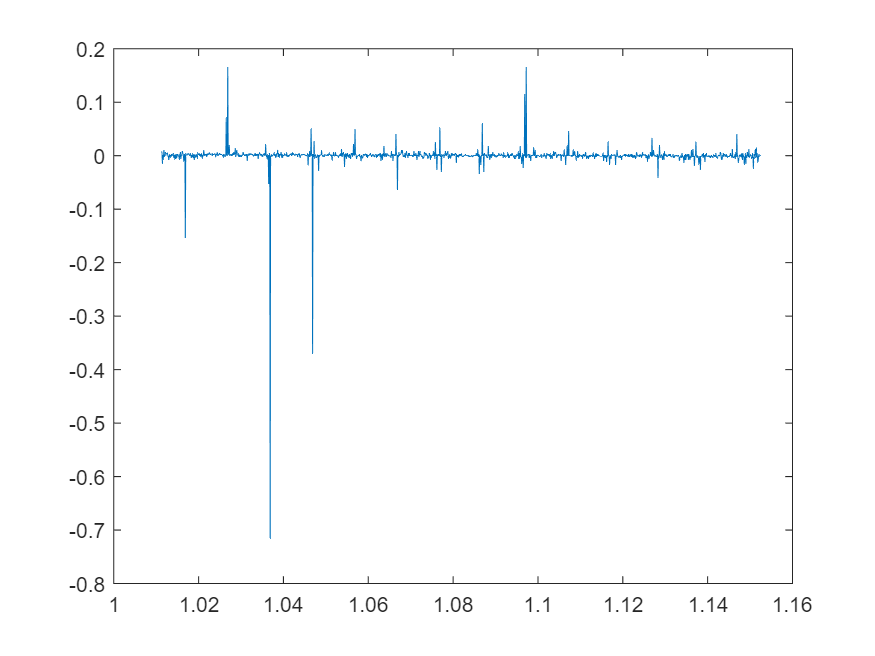

% hold on
% plot(sigma,ang_fit);
% hold off
plot(sigma,angle_fit-ang_fit);

function p = unwrap1(p)
x = p(1);
for n = 2:length(p)
    diff = p(n)-x;
    if diff < 0
        x = p(n);
       p(n) = p(n-1)+diff+pi;
    elseif diff > 0
        x = p(n); 
        p(n) = p(n-1)+diff;
    end
end
end